# Call and Provide ROS Services

ROS supports three main communication mechanisms: topics, services, and actions. Today we will focus on the second type: Services.

From before, we learned about topics/publishers/subscribers as a many-many communication protocal and as an asynchronous protocol. 

*Services*, on the other hand, implement a tighter coupling by allowing **request-response** communication. 

- A *service client* sends a request message to a *service server* and waits for a response. 

- The server will use the data in the request to construct a response message and sends it back to the client. 

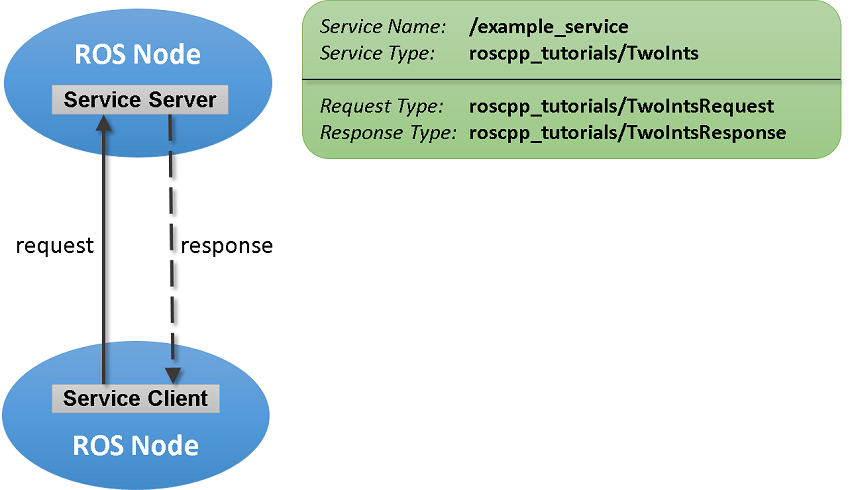

Each service has a **type** that determines the **structure** of the request and response messages. 

Services also have a **name** (a service topic) that is unique in the ROS network.

This service communication has the following characteristics:

- A service request (or service call) is used for one-to-one communication. A single node will house the service client and initiate a request that only the service server (housed in a different node) will receive and process before sending back a response.

- A **service client** and a **service server** are tightly coupled when a* service call* is executed. The server needs to exist at the time of the service call and once the request is sent, the client will block until a response is received.

This live notebook shows you how to:

- Create a callback function that will tell the server what to do

- Create service servers via `ros.ServiceServers` (or `rossvcserver` ) to advertise a service to the ROS network. 

- Create service messages via the `rosmessage` function

- Create service clients via `ros.ServiceClient` (or rossvcclient) to issue requests to the server.

- Initiate the service call

- Find information about services in the network via the `rosservice` helper method.

In its simplest form, code to create a service server/client/call might look as follows:

server = rossvcserver('/test', 'std_srvs/Empty', @exampleHelperROSEmptyCallback, 'DataFormat', 'struct')
client = rossvcclient('/test','DataFormat','struct');
call(client)

Do not yet run this code, but let's flesh out more of the details and possibilities.

## 01 Toy Example

### A. Create Service Server

### rosservice list

Earlier we learned to loook at special ros helper methods like rosnodes or rostopic:

rosnode list

rostopic list

Services have a similar helper method `rosservice`:

rosservice list

rosservice info /test
rosservice type /test

#### Service Servers

We are now ready to explore service servers. 

Suppose you want to make a simple service server that displays the following message when the client calls:

        `-------------------------------------------------------------------`

        `Service Server is running.`

        `ROS Service client issued a call`

        `Would normally process input resp and produce a useful output again in resp`

        `-------------------------------------------------------------------`

To this end, 

- Create the service server using the ros.ServiceServer (or [`rossvcserver`](docid:ros_ref.bupf5_j_11)`)` command. You will need to specify a few things:

- Specify the host node (if using ros.ServiceServer, not necessary with rossvcserver)

- Specify the service topic

- Specificy the service message type

- Specify a "**callback function**" which will specify the behavior of the server. Callbacks will take a function handle @. The function will be defined in a separate .m file. This function will require the following declaration style: 

`        function`` response = serviceCallback(src,reqMsg,defaultRespMsg)`

- Specify a structure data format.

For faster performance, use services with messages in structure format.

node = ros.Node('node');
test_server = ros.ServiceServer(node, ...                                % Note: if node is not provided, the service is attached to the global node
                                "/test", ...                             % Service Topic
                                "std_srvs/Empty", ...                    % Service msg type
                                @exampleHelperROSEmptyCallback, ...      % Callback with its input arguments, 0 in this case
                                "DataFormat","struct")                   % Structure

Note: `rossvcserver` can also be used instead of `ros.ServiceServer. If so, no need to include a node. The global node is assumed.`

After creating the rosservice server object, you can identify this service by its service topic `/test` when you list all services in the ROS network.

rosservice list

You can get more information about your service using [`rosservice`](docid:ros_ref.bupf5_j_7)` info`. The global node is listed as node where the service server is reachable and you also see its `std_srvs/Empty` service type. 

rosservice info /test

### B. Callback Function

Let's take some time to analyze the callback function. 

The callback function will be an independent m file with a declaration of the following type:

`    resp = ``callback_function_name``(~,req,resp)`

This is how callbacks work:

- Call back functions get automatically called anytime a client makes a request via the `call `method 

- The request message gets copied into req (currently empty). 

- The response occurs into places: (i) resp as an input (even though it is designed to be an output). You need to here to set the resp to whatever manipulation you do of req; (ii) output of the function (i.e. resp = callback_function_name). 

- The client then receives the output answer and sets it equal to its output variable. 

- The output variable can then be used to do further operations.

Let's take a look at a toy callback:

exampleHelperROSEmptyCallback

### C. Creating a ROS Service Client

Use service clients to request information from a ROS service server. 

To create a client object, use ros.ServiceClient( or [`rossvcclient`](docid:ros_ref.bupf5_j_10)`)` call that takes:

- a service topic name and

- a struct data format

Let's create a service client for the `/test` service that we just created.

test_client = rossvcclient("/test", ...              % Service topic
                           "DataFormat","struct")    % Structure

Note: `rossvcclient` can also be used instead of `ros.ServiceClient`

### D. ROS Service Messages

ROS Service clients need to have service messages that corresponds to the service topic type. 

When we called test_server, we set its type as "std_srvs/Empty" (this is a completely empty message with nothing inside).

For example, run the following:

rosmessage('std_srvs/EmptyRequest')

We can use rosmessage to create a service message of this type in two ways:

- Pass a service object to the message (either test_server or test_client)

- Pass the type directly (i.e. 'std_srvs/Empty', 'DataFormat', 'struct')

test_req = rosmessage(test_server)          % Create your test request message
% test_req = rosmessage(test_client)        % Other possibilities
% test_req = rosmessage('std_srvs/Empty', 'DataFormat', 'struct')

### E. Having the Client Call the Server

In the next section, we will make our first call from the client to the server. 

In its simplest form, the call includes:

- The service client object

- The service message

- And an output variable to collect the response.

 test_resp = call(test_client, test_req)  

### F. Checking Connectivity

If we want to be more careful about checking that the connection is established. then there are two general steps we need to follow:

- Confirm the service server *exists* (do not assume it exists, things can fail to start/crash or plain forget to launch it!)

- Try to *make a connection* to the server

- Only when the connection exists, *make the call*

01 Confirm the Service Server exists via `waitForServer.`

`waitForServer `takes 2 input arguments: 

- Service Client Object

- A tuple 'Name', 'Value' to establish the timeout time.

If the service server exists, waitforServer exits without error. If it does not exist it will send out an exception (or error) saying that the /test service was not available.

waitForServer(test_client,"Timeout",3) % todo: this is best done inside a try-catch block to catch exceptions. 

Once we confirm the existence of the server, we use the [`call`](docid:ros_ref.buqbgqj) function to call the service server which will return a response. In this case, we will explore a more sophisticated way of collecting outputs from `call` including status messages. 

Pay attention to the following points:

- The test service server you created earlier will return an empty response. 

- Place a break point inside the `exampleHelperROSEmptyCallback` callback to see how it gets called when we issue the `call` method. That callback will display the string *"A service client is calling", *which will show in your command window. 

- As with waitForServer, it is possible to set a `Timeout` parameter to ensure that we receive a timely response. Otherwise a fix needs to be in place.

[resp,status,status_text]  = call(test_client, ...   % Client object has access to the service topic
                                     test_req, ...        % Service message, currently empty
                                     "Timeout",3)         % Timeout

`call` issues 3 outputs:

- `test_resp:`     contains the output of the server and would be used to then further do something in your code.

- `status`:            true or false indicates success or faillure

- `status_text: string indicating state of service server... i.e. what kind of failure might have ocurred`

### Handling Broken Connections

Let's consider a case where the Service Server does not exist or has failed for some reason. 

Delete your service server object:

clear test_server

Let's issue the waitForServer call once again:

waitForServer(test_client,"Timeout",3)

What happens after the timeout?

#### Try-Catch Block

We do not want our code to fail. Otherwise it crashes and prevents further execution. 

A way to handle errors in programming is through what is called a `'try-catch'` block. 

You put the code you want to test inside the try block, if it fails, you do whatever is in the catch. 

Inside the try block we call `waitForServer` to check if we can connect to the server. 

If that fails, display a warning message and perhaps re-start the test_server, or choose another operation...

try
    waitForServer(test_client,"Timeout",3)
    disp('Successfully connected to the service server...')
catch
    disp('No service server running. Try running again...')
    test_server = ros.ServiceServer(node,"/test","std_srvs/Empty",@exampleHelperROSEmptyCallback,"DataFormat","struct") 
end

Similarly, another round of checks can happen when we call the server from the client. 

We can again use a try-catch block or alternatively use the status output of call and use that to inform a decision. 

See this example:

numCallFailures = 0;
[resp,status,statustext] = call(test_client, test_req, "Timeout",3);

% Use conditional statements to proceed

% Failure
if ~status % I.e. failure (when call fails, status = 0. ~0 is the same as true. So, we enter this section upon failure.

    numCallFailures = numCallFailures + 1;
    fprintf("Call failure number %d. Error cause: %s\n", numCallFailures, statustext)

% Success
else
    % Display the output of your server via resp
    disp(resp) % We use display here since we know the server only produces a string output. 
end

## 02 Create a Service for Adding Two Numbers

Start by resetting variables:

clear

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 8


Let's try something simple: a service server that adds two numbers a & b and returns a sum. Inputs a & b will be encoded in an existing structure called `roscpp_tutorials/TwoIntsRequest`. The answer will go onto a separate message type `roscpp_tutorials/TwoIntsResponse.`

In its simplest form, six lines of code would create a server, create a client, populate the message, call the client, and then receive the response:

sumserver = rossvcserver("/sum","roscpp_tutorials/TwoInts",@exampleHelperROSSumCallback,"DataFormat","struct")

physmsg = struct with fields:
      MessageType: 'gazebo_msgs/SetPhysicsPropertiesRequest'
         TimeStep: 0
    MaxUpdateRate: 0
          Gravity: [1×1 struct]
        OdeConfig: [1×1 struct]


sumclient = rossvcclient("/sum","DataFormat","struct")
sumreq = rosmessage(sumclient);
sumreq.A = int64(2);
sumreq.B = int64(1)
sumresp = call(sumclient,sumreq,"Timeout",3)

Let's break it down step-by-step:

### A. Understanding the Service Request and Response Message

#### Request Service Message

In matlab, service messages have two versions: request & response. 

- Request: contains inputs to the service server

- Response: contains the output that returns to the client call function

For this example, the **request** will use a pre-existing message type called `roscpp_tutorials/TwoIntsRequest `that contains 2 integers, `A` and `B`.

Examine via  rosmessage:

rosmessage('roscpp_tutorials/TwoIntsRequest', 'DataFormat','struct')

Or the `rosmsg show `helper call:

rosmsg show roscpp_tutorials/TwoIntsRequest

Important:

Notice the type here. It's not a double, it's an int64. When you create your message, you will need to ***cast*** your variable value to an int64. 

#### Response Service Message

The response message in turn is defined as:

rosmessage('roscpp_tutorials/TwoIntsResponse', 'DataFormat','struct')

Before we actually create the official service message, let's creat a service server and service client first. Their types will help us more robustly create the type for the message later on.

### B. Create the Service Server

As before, to create the service server, we need a service topic, a service message type, a callback, and the data format. 

`Importantly, we will need a callback that takes a handle with two inputs and adds them up together. `

`Let's examine the callback (do Ctrl+D on the script):`

exampleHelperROSSumCallback

Let's create a service server with `rossvcserver` (no need to assign a node in this method):

sumserver = rossvcserver("/sum", ...                        % Service topic
                         "roscpp_tutorials/TwoInts", ...    % Service message type
                         @exampleHelperROSSumCallback, ...  % Callback script
                         "DataFormat","struct")             % Structure

### C. Create the Service Client

Asb before, to create a service client, just provide the service topic:

sumclient = rossvcclient("/sum","DataFormat","struct")

#### E. Creating the Service Message

We are now ready to create the message. This is best implemented by passing the `service client object` as the type:

sumreq = rosmessage(sumclient)

Now we can set the fields A and B of sumreq. I will randomly select an integer between 1 and 100 and cast it as an int64:

sumreq.A = int64( randi(100) );         % Need to convert from double to int64
sumreq.B = int64( randi(100) );         % randi samples random integers between 1 and 100 from a uniform distribution

Note:

We have not cretead a resopnse yet. When the client call's the ServiceServer matlab automatically assigns the correct type to the ouput. I will bring this up later when it comes up.

### E. Client Calls Server

Now, we can call the Service Server and add the two input numbers. 

We will: (i) ensure the connection and then (ii) make the call:

Check connection:

try
    waitForServer(sumclient,"Timeout",3);
    disp('Successfully connected to the service server...');
catch
    disp('No service server running. Try running again...');
    sumserver = ros.ServiceServer("/sum", "roscpp_tutorials/TwoInts", @exampleHelperROSSumCallback,"DataFormat","struct");
end

Call the client:


numCallFailures = 0;
[resp,status,statustext] = call(sumclient, sumreq, "Timeout",3);

% Use conditional statements to proceed
% Failure
if ~status % I.e. failure (when call fails, status = 0. ~0 is the same as true. So, we enter this section upon failure.

    numCallFailures = numCallFailures + 1;
    fprintf("Call failure number %d. Error cause: %s\n", numCallFailures, statustext)

% Success
else
    % Display the output of your server via resp
    disp(resp) % We use display here since we know the server only produces a string output. 
end

## Shut Down ROS Network

Clear data

clear

Shut down the ROS master and delete the global node.

rosshutdown

## 03 Interacting with Gazebo

In this section, we will have interactions with our simulator.

Gazebo ha a number of services that let you interact with the similuator. 

To connect matlab with the simulator:

- Start your VM

- Get your VM hostname via the command: hostname -I (i.e. 192.168.122.128)

- Get your windows IP address (i.e. 192.168.122.1)

- Run rosinit with hostanme, port number, and NodeHost:

rosinit("192.168.122.128",11311,"NodeHost","192.168.122.1")

#### Understanding the Model State

Gazebo lets you move models dynamically via the service topic: `gazebo/set_model_state`

rosservice list

This service has a service message of type `gazebo_msgs/SetModelState (which includes gazebo_msgs/SetModelStateRequest and gazebo_msgs/SetModelStateResponse):`

rosservice info gazebo/set_model_state

Examine the message type:

req = rosmessage('gazebo_msgs/SetModelStateRequest', 'DataFormat', 'struct')

Where, `req` is a structure with `ModelState` as another internal structure:

req.ModelState

Note that ModelState now reveals it has 4 fields:

- ModelName (string): will be the name of the model (i.e. an object) 

- a Pose (position and orientation)

- a Twist (linear velocity and angular velocity), and

- a Reference frame.

Note that you can see a list of all the models in the side pane of Gazebo:

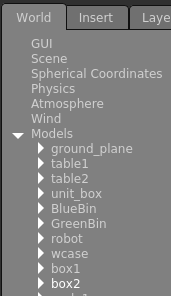

You can also click on any model in Gazebo to reveal its properties:

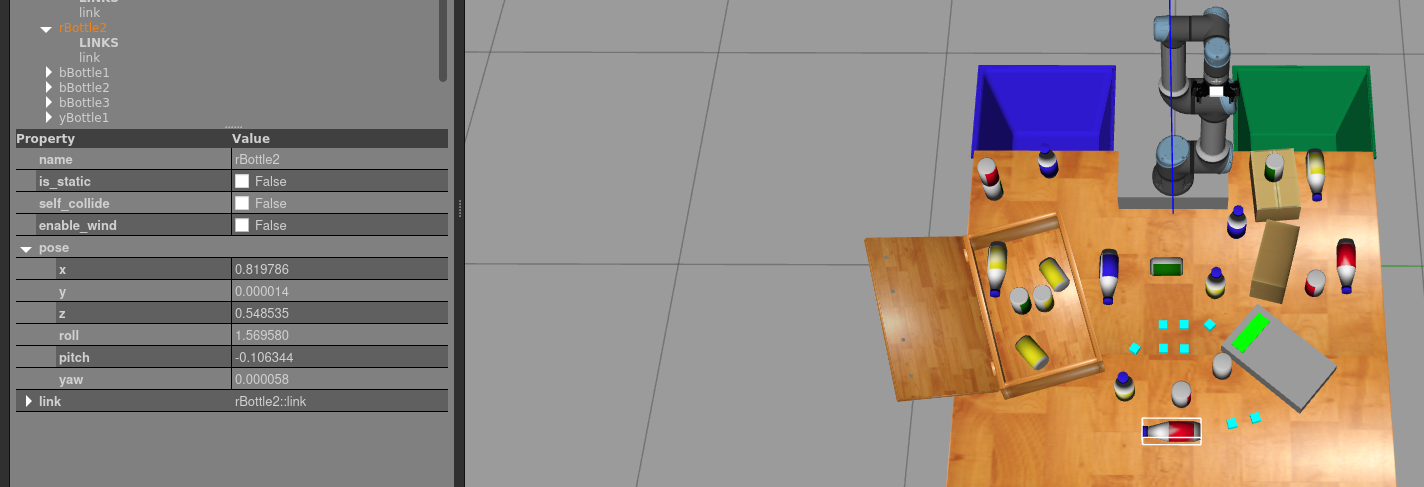

In essence, filling up this message is equivalent to saying that you want to move an object to a different location/orientation or give it a velocity!

In this case, we do not need to create a service server. It has already been created by the gazebo simulator.

Here, we only need to create the client:

gazebo_model_client = rossvcclient('/gazebo/set_model_state', 'DataFormat', 'struct')

Note: it may take several seconds to create due to the delay with the VM.

#### Create the Request message

We can use the req message we created earlier.

Alternatively, we could have created it directly from the gazebo_model_client object:

%set_model_msg = rosmessage(gazebo_model_client) 

### Populate the Message

As noted earlier, the message has lots of information on it. Fortunately you do not have to fill it all out. Imagine you want to take the red bottle I highlighted earlier and change its pose. 

In this case, set the model name and then the Pose field:

req.ModelState.ModelName = 'rBottle2'
req.ModelState.Pose.Position.X = 0.9
req.ModelState.Pose.Position.Z = 0.6

#### Call the Client

For this section, let's do simple client calls, to facilitate the process. As you get ready to call the client, this will be the first time that you see the service do something interesting. 

Before you run the following code, make sure you can see your simulation from a top-down view from where the red bottle 2 is clearly seen:

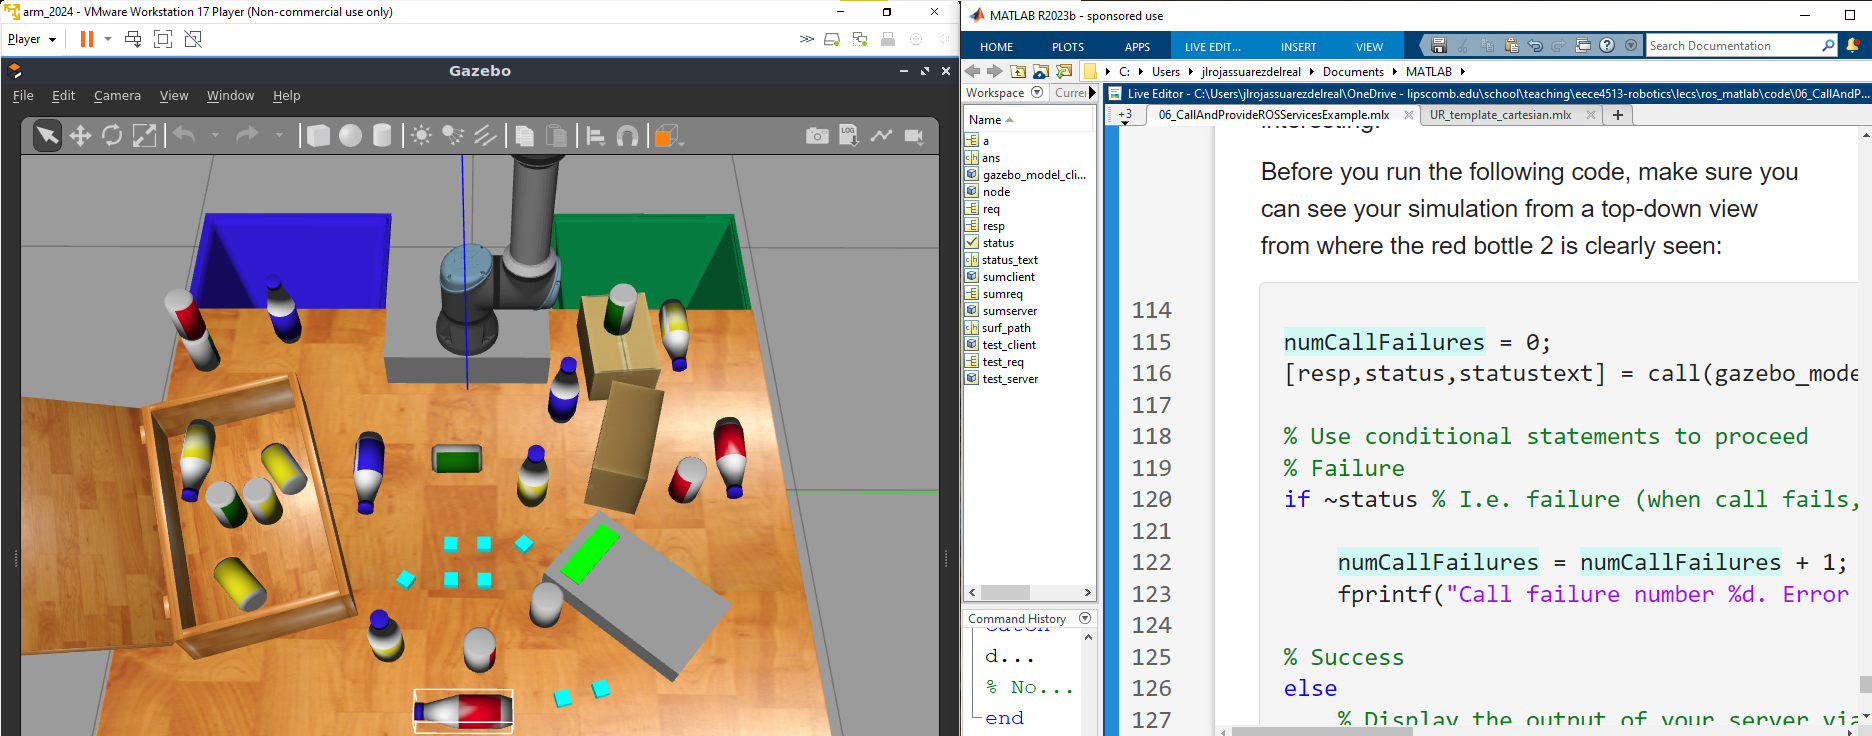

call(gazebo_model_client, req);

### Other Gazebo Services

As before, we can look at different gazebo services via rosservice list:

rosservice list

Note: /gazebo/reset_world and /gazebo/set_physics_properties. 

### Reset World

Create a client, a message (which will be empty). When you call see the effects in the simulator::

resetclient = rossvcclient('/gazebo/reset_world', 'DataFormat','struct')
resetmsg = rosmessage(resetclient) % type is std_srvs/EmptyRequest... so we can call without populating
call(resetclient,resetmsg)

### Gazebo Set Parameters

physclient = rossvcclient('/gazebo/set_physics_properties', 'DataFormat', 'struct')
physmsg = rosmessage(physclient)

Check out the physmsg structure which has a gravity field inside:

physmsg.Gravity % currently gravity is set to 0 in all directions. 

Slightly change the gravity in the z-direction:

physmsg.Gravity.X = 2

What would happen if we call the service server with a message that has gravity set to 0?

call(physclient, physmsg)

## Shut Down ROS Network

Remove the sample nodes and service servers from the ROS network.

exampleHelperROSShutDownSampleNetwork

Shut down the ROS master and delete the global node.

rosshutdown

*Copyright 2014-2021 The MathWorks, Inc.*